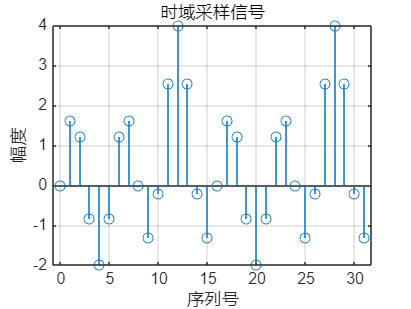

clc;clear;
f = 50;  % 基波频率
A = [0.5, 1, 0.5, 2];  % 振幅
phi = [0, pi/2, pi, -pi/2];  % 相位
N = 16;  % 采样频率倍数
L = 2 * N;  % 采样点数
fs = N * f;  % 采样频率
T = 1 / fs;  % 采样间隔
t = (0:L-1) * T;  % 采样时间
tt=0:L-1;%序列号
s = zeros(size(t));  % 初始化采样信号
for k = 1:length(A)
    sk = A(k) * cos(2 * pi * (k-1) * f * t + phi(k));
    s = s + sk;
end
stem(tt, s)
xlabel('序列号')
ylabel('幅度')
title('时域采样信号')
grid on